# Hands-On: Step-Invariant Transform

## Introduction

Consider the scheme

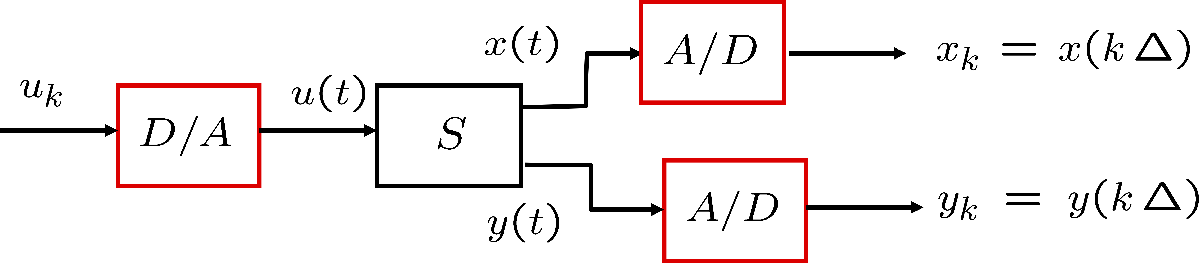

where the LTI dynamic system is described by means of state equations


$$				\left\{
				\begin{array}{lcl}
					\dot{x}(t) &=& A_{c} x(t) + B_{c} u(t) \\[1 em]
					y(t) &=& C_{c} x(t) + D_{c} u(t)
				\end{array}
				\right.$$


Both state variables and outputs are sampled by means of an **ideal sampler**, whereas the inputs to the system are converted from discrete- to continuous-time using a **ZOH**. 

`T`he discrete-time state equations for the dynamic system considered are


$$	\left\{
				\begin{array}{rcl}
					x\big((k+1)\Delta\big) &=& A_{d} \,x\left(k \Delta \right) + B_{d} \,u\left(k \Delta \right) \\[1 em]
					y\left(k \Delta \right) &=& C_{d} \,x\left(k \Delta \right) + D_{d} \,u\left(k \Delta \right)
				\end{array}
				\right.$$


where the formulas


$$\matrix{
\displaystyle A_{d} = e^{A_{c} \Delta}& \displaystyle C_{d} = C_{c}  \cr
\displaystyle B_{d} = \int_{0}^{\Delta} \, e^{A_{c} r} B_{c} \, d r & D_{d} = D_{c}
}$$


describe the so called **step-invariant transform**.

In this live script, we illustrate how to use Matlab to apply the step-invariant transform.

What you will learn: 

- How to apply the step-invariant transform, when the continuous-time system has a state space description using some symbolic parameters (so you need some symbolic variables in MATLAB to describe such an LTI system);

- How to apply the step-invariant transform when the continuous-time LTI system state equations have been used to create an `LTI system` object in MATLAB.

## First Scenario: an LTI System State-Space Description with Symbolic Parameters

Consider

$\left\{ 
\begin{array}{lcl}
\dot{x} &=& \left[ \begin{array}{cc}
0 & 1 \\ 0  &-a
\end{array} \right] \, x + \left[ \begin{array}{c}
0 \\ K
\end{array} \right]\, u\\[2 em]
y &=& \left[ \begin{array}{cc} 1 & 0 \end{array} \right] \, x
\end{array}
\right.\quad a \in \mathbf{R}\,,\; K \in  \mathbf{R}$ (1)

and let's determine the discrete-time description, by sampling with ZOH and ideal samplers.

Applying the step-invariant transform

$A_d = e^{A_{c}\,\Delta} = e^{A_{c}\,t} \Bigg|_{t=\Delta} = \mathcal{L}^{-1} \left\{ \left( sI-A_{c} \right)^{-1} \right\}\Bigg| _{t=\Delta}=\left[ \begin{array}{cc}
1 & \displaystyle \frac{1}{a}\,\left( 1-e^{-a\,\Delta} \right) \\[8 mm]
0 & e^{-a\,\Delta}
\end{array} \right]$  (2)


$$B_{d} = \displaystyle \int_{0}^{\Delta} e^{A_{c}\,r}\,B_{c}\,dr = \left[ \begin{array}{l}
\int_{0}^{\Delta} \displaystyle \frac{K}{a}\left( 1-e^{-a\,r} \right) \,dr \\[6 mm]
\int_{0}^{\Delta} \displaystyle K e^{-a\,r} \, dr
\end{array} \right]$$



$$C_d =C_c \qquad D_d = D_c$$


### Using MATLAB and the Symbolic Math Toolbox

clear
close all
clc

sympref('HeavisideAtOrigin', 1); % setting the preferences 
                                 % for the Symbolic Math Toolbox
sympref('FloatingPointOutput', 0);
sympref % show the actual settings

ans = struct with fields:
           FourierParameters: [1    -1]
           HeavisideAtOrigin: 1
            AbbreviateOutput: 1
               TypesetOutput: 1
         FloatingPointOutput: 0
      PolynomialDisplayStyle: 'default'
    MatrixWithSquareBrackets: 0


Declare the parameters $a$ and $K$as symbolic variables

syms a K

Then assign the system matrices

Ac = [0 ,  1; ...
     0 ,  -a]

$$Ac = \left(\begin{array}{cc} 0 & 1\\ 0 & -a \end{array}\right)$$

Bc = [0; ...
      K]

$$Bc = \left(\begin{array}{c} 0\\ K \end{array}\right)$$

Cc = sym([1 , 0]), Dc = sym(0)

$$Cc = \left(\begin{array}{cc} 1 & 0 \end{array}\right)$$

$$Dc = 0$$

Declare the symbolic variables $s$, $t$, and the sampling time $\Delta$.  We need these symbolic variables to compute the symbolic expressions of the discrete-time repserentation fo the LTI system, according to the step-invariant trasform, reported in Eq. (2).

syms s t Delta

### Computation of the Discrete-Time Description Matrix A

Compute the matrix $A_d = e^{A_{c}\,\Delta} $, according to Eq. (2).

In order to evaluate the matrix exponential, start computing the Laplace transform of it:


sIA = s*eye(size(Ac))-Ac

$$sIA = \left(\begin{array}{cc} s & -1\\ 0 & a+s \end{array}\right)$$

sIAinv = inv(sIA)

$$sIAinv = \left(\begin{array}{cc} \frac{1}{s} & \frac{1}{s\,\left(a+s\right)}\\ 0 & \frac{1}{a+s} \end{array}\right)$$

Now, determine the matrix exponential, by means of the inverse Laplace transform:


$$e^{A_{c}\,t} = \mathcal{L}^{-1} \left\{ \left( sI-A_{c} \right)^{-1} \right\} $$


expAc_t = ilaplace(sIAinv,s, t)

$$expAc\_t = \left(\begin{array}{cc} 1 & \frac{1}{a}-\frac{{\mathrm{e}}^{-a\,t}}{a}\\ 0 & {\mathrm{e}}^{-a\,t} \end{array}\right)$$

Finally, evaluate the symbolic expression $e^{A_c t}$ at $t=\Delta$

Ad = simplify(subs(expAc_t, t, Delta))

$$Ad = \left(\begin{array}{cc} 1 & -\frac{{\mathrm{e}}^{-\Delta \,a}-1}{a}\\ 0 & {\mathrm{e}}^{-\Delta \,a} \end{array}\right)$$

We found the expression of the matrix $A_d$. Please compare with the theoretical expression in the Eq.(2).

#### Remark

For details on the command `symplify`, please use the `help` or the `doc` commands.

### An Alternative Use for the Command `subs`

What if  we would assign a numerical value to the parameter $a$, and/or to the sampling time $\Delta$?

Easy! We can use the command `subs`. 

Example: assign the values $a=10$

AdEX1 = subs(Ad,a,10)

$$AdEX1 = \left(\begin{array}{cc} 1 & \frac{1}{10}-\frac{{\mathrm{e}}^{-10\,\Delta }}{10}\\ 0 & {\mathrm{e}}^{-10\,\Delta } \end{array}\right)$$

Now suppose we want assign the values $a=4.75$, and as sampling time $\Delta = 10^{-3}$ s

AdEX2 = subs(Ad,{a,Delta}, {4.75, 1e-3})

$$AdEX2 = \left(\begin{array}{cc} 1 & \frac{4}{19}-\frac{4\,{\mathrm{e}}^{-\frac{19}{4000}}}{19}\\ 0 & {\mathrm{e}}^{-\frac{19}{4000}} \end{array}\right)$$

### Computing the Matrix B of the Discrete-Time Description

We should evaluate


$$B_{d} = \displaystyle \int_{0}^{\Delta} e^{A_{c}\,r}\,B_{c}\,dr $$


Bd = int(expAc_t*Bc, t, 0, Delta)

$$Bd = \left(\begin{array}{c} \frac{K\,\left({\mathrm{e}}^{-\Delta \,a}+\Delta \,a-1\right)}{a^{2}}\\ -\frac{K\,\left({\mathrm{e}}^{-\Delta \,a}-1\right)}{a} \end{array}\right)$$

Then we can use the command `subs` to assign numercal values to the parameters and to the sampling period. For example

BdEX2 = subs(Bd, {a, K, Delta}, {4.75, -2, 1e-3})

$$BdEX2 = \left(\begin{array}{c} \frac{3981}{45125}-\frac{32\,{\mathrm{e}}^{-\frac{19}{4000}}}{361}\\ \frac{8\,{\mathrm{e}}^{-\frac{19}{4000}}}{19}-\frac{8}{19} \end{array}\right)$$

### Computing the Matrix C and D of the Discrete-Time Description

Easily, according to Eq. (2)


$$C_d = C_c \qquad D_d = D_c$$


Thus

Cd = Cc

$$Cd = \left(\begin{array}{cc} 1 & 0 \end{array}\right)$$

Dd = Dc

$$Dd = 0$$

### First Scenario: Final Remaks

Please note: the resulting matrices $A_d\,,\; B_d\,,\; C_d$, and $D_d$ are symbolic variables, so you can not create an LTI object using such matrices. In order to create an LTI object, you have to convert the symbolic matrices in numeric ones:

Adr = double(AdEX2)

Adr =     1.0000    0.0010
         0    0.9953


Bdr = double(BdEX2)

Bdr =    -0.0000
   -0.0020


Cdr = double(Cd)

Cdr =      1     0


Ddr = double(Dd)

Ddr = 0

Finally

sysD_EX2 = ss(Adr, Bdr, Cdr, Ddr, 1e-3)

sysD_EX2 =
 
  A = 
              x1         x2
   x1          1  0.0009976
   x2          0     0.9953
 
  B = 
               u1
   x1  -9.984e-07
   x2   -0.001995
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.001 seconds
Discrete-time state-space model.



## Second Scenario: an LTI System State-Space Description with Numerical Matrices

Let's consider the continuous-time LTI system


$$\left\{ \begin{array}{rcl}
			\dot{x}(t) &=& \left[ \begin{array}{cc} 
												0 & 1\\0 & -1 
											\end{array} \right] \cdot x(t) + \left[\begin{array}{c} 0 \\ 10  \end{array} \right] \cdot u(t) \\[1em]
			y(t) &=& \left[ \begin{array}{cc}
									 1 & 0
									\end{array}  \right] \cdot x(t)
			\end{array} \right.$$


Please note: it is the same example as in Eq. (1), with parameters values $a=1\,,\; K = 10$. 

clear
close all
clc
sympref('default'); % resetting the Symbolic Math Toolbox preferences

% assigning the numeric matrices Ac, Bc, Cc, Dc
Ac = [0, 1;...
      0,  -1];
Bc = [0; 10];
Cc = [1, 0]; Dc = 0;
sysC = ss(Ac, Bc, Cc, Dc)

sysC =
 
  A = 
       x1  x2
   x1   0   1
   x2   0  -1
 
  B = 
       u1
   x1   0
   x2  10
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



In this scenario, the matrices $A_c\,,\;B_c\,,\;C_c$, and $D_c$ are numeric matrices, so we can compute the step-invariant transform easily using the Control System Toolbox command `c2d`. Chosen as sampling period the value $\Delta = 10^{-1} $ s, the discrete-time description is computed simply by typing 

Delta = 1e-1; % assigning the sampling period
sysD_ExN = c2d(sysC, Delta)

sysD_ExN =
 
  A = 
            x1       x2
   x1        1  0.09516
   x2        0   0.9048
 
  B = 
            u1
   x1  0.04837
   x2   0.9516
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.1 seconds
Discrete-time state-space model.



## Summary

In this live script, we illustrated how to use Matlab to apply the step-invariant transform in order to obtain a discrete-time description of a continuous-time LTI system, fed by inputs converted from discrete- to continuous-time using a ZOH and sampling both state variables and outputs through an ideal sampler.

Using this live script you have learnt:

- How to apply the step-invariant transform, when the continuous-time system has a state space description using some symbolic parameters;

- How to apply the step-invariant transform when the continuous-time LTI system state equations have been used to create an `LTI system` object in MATLAB.